# Exercises 5.6

4. For the element at right, determine the corresponding nodal forces if anormal tractiontn = 1kPa is applied in the shaded face..

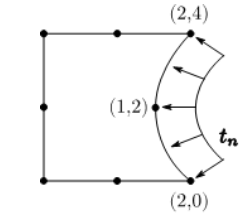

clear all
clc

type = 8;
C = [2 4; 2 0; 1 2];
tn = 1;
q = 3;
F = compute_F(type, C, tn, 3);
vpa (F, 3)

$$ans = \left(\begin{array}{c} -0.667\\ 0.667\\ -0.667\\ -0.667\\ -2.67\\ 0 \end{array}\right)$$

function F = compute_F(type,C, P, q)
if type == 4
    nnodes = 2;
elseif type == 8
    nnodes = 3;
elseif type == 12
    nnodes = 4;
else type = 0;
end
ndof   = 2;
F      = zeros(ndof*nnodes,1);
for i = 1: q
    Q       = quadrature_lin(q);
    xi      = Q (i, 1);
    w       = Q (i, 2);
    [dN, n] = lin_shape_form(nnodes,xi);
    J       = C'*dN;
    N = zeros(nnodes*ndof,ndof);
    for j = 1: nnodes
    k = (j-1) * ndof;
    I = eye(2);
    N([k+1 k+2], :) = I*n(j); 
    end
    tn = [J(2) -J(1)];
    jn = tn/norm(tn);
    F = F + N*P*jn'*norm(J)*w;
end
end  